# Bengali Speech Recognition (Words)

## Creating Training and Validation Datastore

dataset_path = "C:\Users\SB Shuvo\OneDrive - BUET\312_SuptaFolder\trainer\suptaTrained\dspProjectSamples1Sec";
ads = audioDatastore(dataset_path, ...
    IncludeSubfolders=true, ...
    FileExtensions=".wav", ...
    LabelSource="foldernames");
[adsTrain, adsValidation]= splitEachLabel(ads, 0.70);


## Computing Auditory Spectrograms

fs = 16e3; % Known sample rate of the data set.

segmentDuration = 1;
frameDuration = 0.025;
hopDuration = 0.010;

segmentSamples = round(segmentDuration*fs);
frameSamples = round(frameDuration*fs);
hopSamples = round(hopDuration*fs);
overlapSamples = frameSamples - hopSamples;

FFTLength = 512;
numBands = 50;


afe = audioFeatureExtractor( ...
    SampleRate=fs, ...
    FFTLength=FFTLength, ...
    Window=hann(frameSamples,"periodic"), ...
    OverlapLength=overlapSamples, ...
    barkSpectrum=true);
setExtractorParameters(afe,"barkSpectrum",NumBands=numBands,WindowNormalization=false);

x = read(adsTrain);

numSamples = size(x,1);

numToPadFront = floor((segmentSamples - numSamples)/2);
numToPadBack = ceil((segmentSamples - numSamples)/2);

xPadded = [zeros(numToPadFront,1,"like",x);x;zeros(numToPadBack,1,"like",x)];

To extract audio features, call `extract`. The output is a Bark spectrum with time across rows.

features = extract(afe,xPadded);
[numHops,numFeatures] = size(features)

numHops = 98

numFeatures = 50

if ~isempty(ver("parallel"))
    pool = gcp;
    numPar = numpartitions(adsTrain,pool);
else
    numPar = 1;
end


For each partition, read from the datastore, zero-pad the signal, and then extract the features.

parfor ii = 1:numPar
    subds = partition(adsTrain,numPar,ii);
    XTrain = zeros(numHops,numBands,1,numel(subds.Files));
    for idx = 1:numel(subds.Files)
        x = read(subds);
        xPadded = [zeros(floor((segmentSamples-size(x,1))/2),1);x;zeros(ceil((segmentSamples-size(x,1))/2),1)];
        XTrain(:,:,:,idx) = extract(afe,xPadded);
    end
    XTrainC{ii} = XTrain;
end

Converting the output to a 4-dimensional array with auditory spectrograms along the fourth dimension.

XTrain = cat(4,XTrainC{:});

[numHops,numBands,numChannels,numSpec] = size(XTrain)

numHops = 98

numBands = 50

numChannels = 1

numSpec = 368

Scaling the features by the window power and then take the log. To obtain data with a smoother distribution, take the logarithm of the spectrograms using a small offset.

epsil = 1e-6;
XTrain = log10(XTrain + epsil);

Performing the feature extraction steps described above to the validation set.

if ~isempty(ver("parallel"))
    pool = gcp;
    numPar = numpartitions(adsValidation,pool);
else
    numPar = 1;
end

parfor ii = 1:numPar
    subds = partition(adsValidation,numPar,ii);
    XValidation = zeros(numHops,numBands,1,numel(subds.Files));
    for idx = 1:numel(subds.Files)
        x = read(subds);
        xPadded = [zeros(floor((segmentSamples-size(x,1))/2),1);x;zeros(ceil((segmentSamples-size(x,1))/2),1)];
        XValidation(:,:,:,idx) = extract(afe,xPadded);
    end
    XValidationC{ii} = XValidation;
end
XValidation = cat(4,XValidationC{:});
XValidation = log10(XValidation + epsil);

Isolate the train and validation labels. Remove empty categories.

TTrain = removecats(adsTrain.Labels);
TValidation = removecats(adsValidation.Labels);

## Visualize Data

Plot the waveforms and auditory spectrograms of a few training samples. Play the corresponding audio clips.

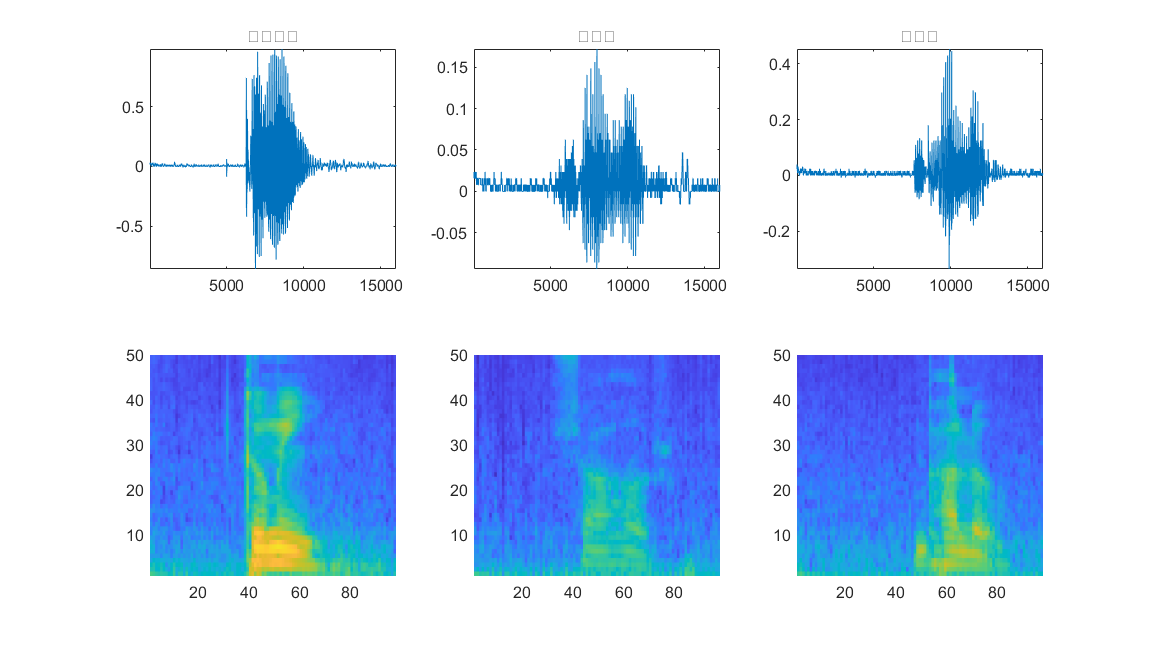

specMin = min(XTrain,[],"all");
specMax = max(XTrain,[],"all");
idx = randperm(numel(adsTrain.Files),3);
figure(Units="normalized",Position=[0.2 0.2 0.6 0.6]);
for ii = 1:3
    [x,fs] = audioread(adsTrain.Files{idx(ii)});

    subplot(2,3,ii)
    plot(x)
    axis tight
    title(string(adsTrain.Labels(idx(ii))))
    
    subplot(2,3,ii+3)
    spect = XTrain(:,:,1,idx(ii))';
    pcolor(spect)
    caxis([specMin specMax])
    shading flat
    
    sound(x,fs)
    pause(2)
end

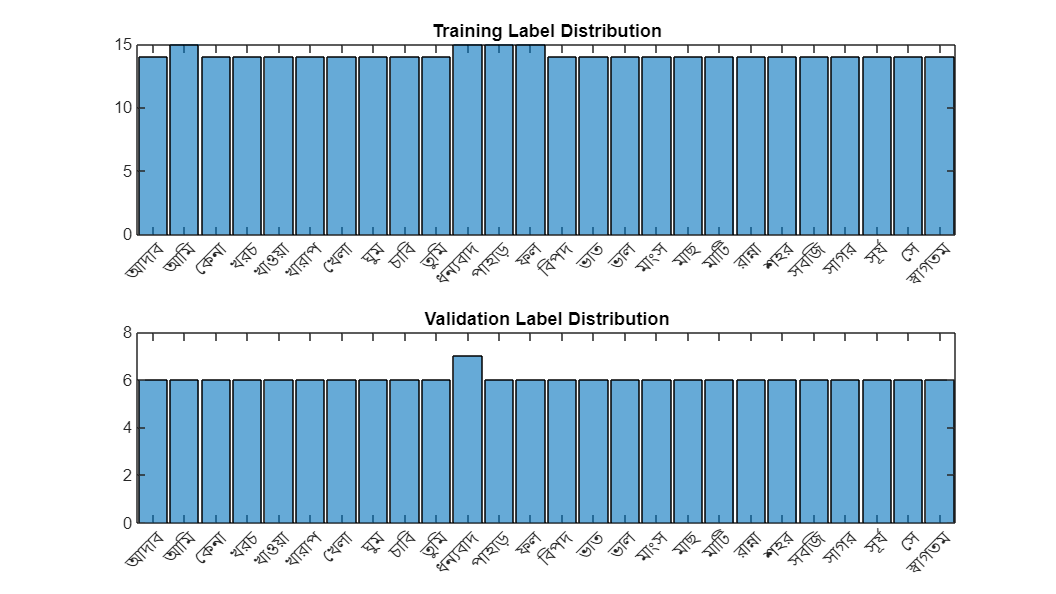

figure(Units="normalized",Position=[0.2 0.2 0.5 0.5])

tiledlayout(2,1)

nexttile
histogram(TTrain)
title("Training Label Distribution")

nexttile
histogram(TValidation)
title("Validation Label Distribution")

## Defining Neural Network Architecture

classes = categories(TTrain);
classWeights = 1./countcats(TTrain);
classWeights = classWeights'/mean(classWeights);
numClasses = numel(categories(TTrain));

timePoolSize = ceil(numHops/8);

dropoutProb = 0.2;
numF = 12;
layers = [
    imageInputLayer([numHops numBands])
    
    convolution2dLayer(3,numF,Padding="same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(3,Stride=2,Padding="same")
    
    convolution2dLayer(3,4*numF,Padding="same")
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,4*numF,Padding="same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer([timePoolSize,1])
    
    dropoutLayer(dropoutProb)
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer(Classes=classes,ClassWeights=classWeights)];

## Training Network

miniBatchSize = 3;
validationFrequency = floor(numel(TTrain)/miniBatchSize);
options = trainingOptions("adam", ...
    InitialLearnRate=3e-4, ...
    MaxEpochs=25, ...
    MiniBatchSize=miniBatchSize, ...
    Shuffle="every-epoch", ...
    Plots="training-progress", ...
    Verbose=false, ...
    ValidationData={XValidation,TValidation}, ...
    ValidationFrequency=validationFrequency, ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropFactor=0.1, ...
    LearnRateDropPeriod=20);

### Training the Network

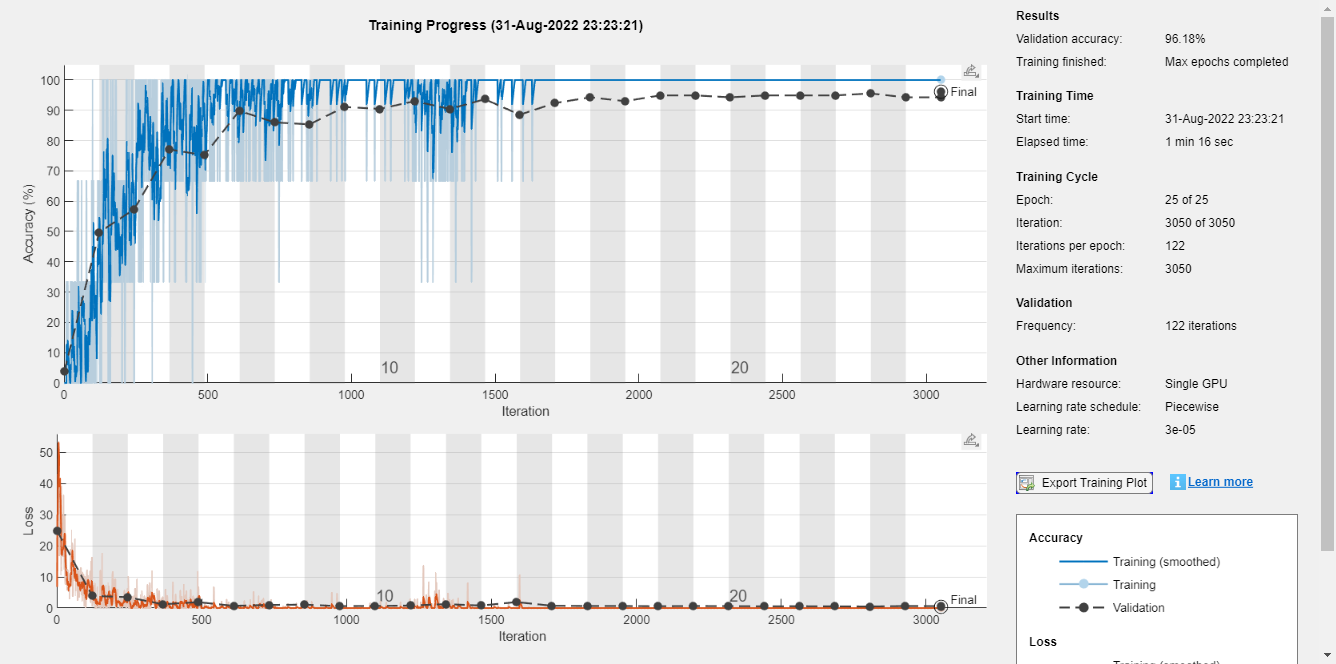

trainedNet = trainNetwork(XTrain,TTrain,layers,options);

## Evaluate Trained Network

YValPred = classify(trainedNet,XValidation);
validationError = mean(YValPred ~= TValidation);
YTrainPred = classify(trainedNet,XTrain);
trainError = mean(YTrainPred ~= TTrain);

disp("Training error: " + trainError*100 + "%")

Training error: 0%


disp("Validation error: " + validationError*100 + "%")

Validation error: 3.8217%


Plotting the Confusion Matrix

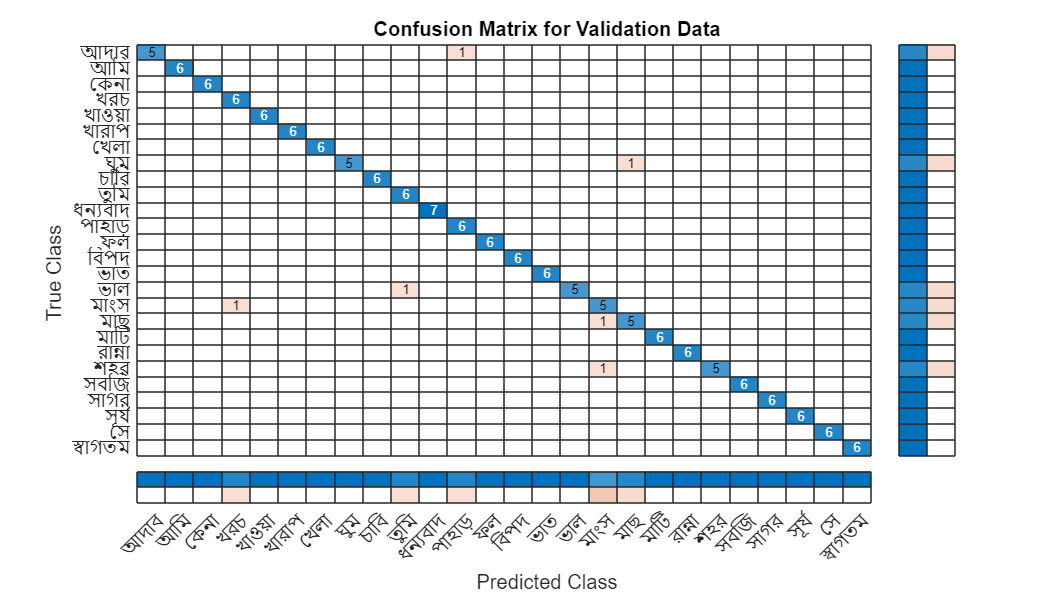

figure(Units="normalized",Position=[0.2 0.2 0.5 0.5]);
cm = confusionchart(TValidation,YValPred, ...
    Title="Confusion Matrix for Validation Data", ...
    ColumnSummary="column-normalized",RowSummary="row-normalized");

info = whos("trainedNet");
disp("Network size: " + info.bytes/1024 + " kB")

Network size: 4655.3584 kB


time = zeros(100,1);
for ii = 1:100
    x = randn([numHops,numBands]);
    tic
    [YPredicted,probs] = classify(trainedNet,x,ExecutionEnvironment="cpu");
    time(ii) = toc;
end
disp("Single-image prediction time on CPU: " + mean(time(11:end))*1000 + " ms")

Single-image prediction time on CPU: 4.2326 ms


% Saving the trained Model for Future Use

% outputDir = "C:\Users\win\OneDrive - BUET\project_supta_deb\312\trainer\suptaTrained\dspProjectSamples1Sec";
% outputFile = fullfile(outputDir, "trained_net_93_percent_val_1_sec_supta_words_with_dhonnobad_2.mat");
% save(outputFile, "trainedNet");
